# 美赛培训第四次课：数学规划与优化模型

% 授课人：Mr.Guo
% 目标：掌握线性规划、整数规划、非线性规划原理与MATLAB实现

## 第一部分：课程回顾与目标设定

% 1.1 前两节课回顾
disp('=== 前两节课回顾 ===')

=== 前两节课回顾 ===


disp('第一课：MATLAB基础与数据处理')

第一课：MATLAB基础与数据处理


disp('✓ 数据导入与清洗 ✓ 统计量计算 ✓ 基础可视化')

✓ 数据导入与清洗 ✓ 统计量计算 ✓ 基础可视化


disp(' ')

disp('第二课：统计分析与假设检验')

第二课：统计分析与假设检验


disp('✓ 相关性分析 ✓ 假设检验 ✓ 回归分析')

✓ 相关性分析 ✓ 假设检验 ✓ 回归分析


disp(' ')


% 1.2 本节课学习目标
disp('=== 本节课学习目标 ===')

=== 本节课学习目标 ===


disp('1. 理解线性规划原理与应用场景')

1. 理解线性规划原理与应用场景


disp('2. 掌握整数规划与0-1规划')

2. 掌握整数规划与0-1规划


disp('3. 学习非线性规划求解方法')

3. 学习非线性规划求解方法


disp('4. 了解多目标优化问题')

4. 了解多目标优化问题


disp('5. 完成生产计划优化实战案例')

5. 完成生产计划优化实战案例


disp(' ')


% 1.3 优化问题概述
disp('=== 优化问题概述 ===')

=== 优化问题概述 ===


disp('优化问题三要素：')

优化问题三要素：


disp('1. 决策变量：需要确定的未知数')

1. 决策变量：需要确定的未知数


disp('2. 目标函数：需要最大化或最小化的函数')

2. 目标函数：需要最大化或最小化的函数


disp('3. 约束条件：决策变量必须满足的限制')

3. 约束条件：决策变量必须满足的限制


disp(' ')

disp('数学形式：')

数学形式：


disp('   min/max  f(x)')

   min/max  f(x)


disp('   s.t.     g(x) ≤ 0')

   s.t.     g(x) ≤ 0


disp('           h(x) = 0')

           h(x) = 0


disp('           x ∈ X')

           x ∈ X



% 准备工作
clear
clc
close all
format short


## 第二部分：线性规划 (Linear Programming)


% 2.1 线性规划原理介绍
disp(' ')

disp('=== 线性规划 (Linear Programming) ===')

=== 线性规划 (Linear Programming) ===


disp('线性规划特征：')

线性规划特征：


disp('• 目标函数是线性的')

• 目标函数是线性的


disp('• 约束条件是线性的')

• 约束条件是线性的


disp('• 决策变量连续')

• 决策变量连续


disp(' ')

disp('标准形式：')

标准形式：


disp('   min     cᵀx')

   min     cᵀx


disp('   s.t.    Ax ≤ b')

   s.t.    Ax ≤ b


disp('           Aeq·x = beq')

           Aeq·x = beq


disp('           lb ≤ x ≤ ub')

           lb ≤ x ≤ ub



% 2.2 简单线性规划示例
disp(' ')

disp('--- 简单线性规划示例 ---')

--- 简单线性规划示例 ---


disp('问题：工厂生产计划优化')

问题：工厂生产计划优化


disp('工厂生产两种产品A和B，单位利润分别为3元和5元')

工厂生产两种产品A和B，单位利润分别为3元和5元


disp('生产限制：')

生产限制：


disp('  1. 原料限制：产品A需要2单位原料，产品B需要1单位原料，总共不超过100单位')

  1. 原料限制：产品A需要2单位原料，产品B需要1单位原料，总共不超过100单位


disp('  2. 工时限制：产品A需要1小时，产品B需要3小时，总共不超过150小时')

  2. 工时限制：产品A需要1小时，产品B需要3小时，总共不超过150小时


disp('  3. 市场需求：产品B最多只能生产40单位')

  3. 市场需求：产品B最多只能生产40单位


disp('目标：最大化总利润')

目标：最大化总利润



% 定义线性规划参数
c = [-3; -5];  % 目标函数系数（求最大化，所以加负号）
A = [2, 1;     % 原料约束系数
     1, 3];    % 工时约束系数
b = [100;      % 原料约束上限
     150];     % 工时约束上限
Aeq = [];      % 等式约束（无）
beq = [];      % 等式约束（无）
lb = [0; 0];   % 决策变量下界
ub = [Inf; 40]; % 决策变量上界（产品B最多40）

% 使用linprog求解线性规划
options = optimoptions('linprog', 'Display', 'iter', 'Algorithm', 'dual-simplex');
[x, fval, exitflag, output] = linprog(c, A, b, Aeq, beq, lb, ub,  options);

LP preprocessing removed 0 inequalities, 0 equalities,
0 variables, and added 0 non-zero elements.

 Iter      Time            Fval  Primal Infeas    Dual Infeas  
    0     0.001   -2.000000e+02   0.000000e+00   1.500000e+00  
    1     0.006   -2.900000e+02   0.000000e+00   0.000000e+00  

找到最优解。




% 显示结果
disp(' ')

disp('=== 求解结果 ===')

=== 求解结果 ===


if exitflag == 1
    disp('求解成功！')
    disp(['生产计划：产品A = ', num2str(x(1)), ' 单位'])
    disp(['           产品B = ', num2str(x(2)), ' 单位'])
    disp(['最大利润：', num2str(-fval), ' 元'])  % 注意：fval是目标函数值，我们求最大化所以取负
    
    % 分析资源使用情况
    disp(' ')
    disp('资源使用分析：')
    resource_used = A * x;
    disp(['原料使用：', num2str(resource_used(1)), '/100 单位'])
    disp(['工时使用：', num2str(resource_used(2)), '/150 小时'])
    
    % 计算松弛变量
    slack = b - A * x;
    disp(['原料剩余：', num2str(slack(1)), ' 单位'])
    disp(['工时剩余：', num2str(slack(2)), ' 小时'])
else
    disp('求解失败，退出标志：', num2str(exitflag))
end

求解成功！


生产计划：产品A = 30 单位


           产品B = 40 单位


最大利润：290 元


资源使用分析：


原料使用：100/100 单位


工时使用：150/150 小时


原料剩余：0 单位


工时剩余：0 小时



% 2.3 线性规划可视化（仅适用于2变量问题）
disp(' ')

disp('--- 线性规划可视化 ---')

--- 线性规划可视化 ---


disp('对于二维问题，我们可以用图形方法求解')

对于二维问题，我们可以用图形方法求解



% 创建约束线
x1 = 0:0.1:60;  % 产品A的范围

% 约束1: 2x1 + x2 ≤ 100 → x2 ≤ 100 - 2x1
constr1 = 100 - 2*x1;
% 约束2: x1 + 3x2 ≤ 150 → x2 ≤ (150 - x1)/3
constr2 = (150 - x1)/3;
% 约束3: x2 ≤ 40
constr3 = 40 * ones(size(x1));

% 可行域下界
feasible_lower = zeros(size(x1));

% 可行域上界（取各约束的最小值）
feasible_upper = min([constr1; constr2; constr3], [], 1);

% 可视化
figure('Position', [100, 100, 1200, 500])

subplot(1, 2, 1)
% 绘制约束线
plot(x1, constr1, 'b-', 'LineWidth', 2, 'DisplayName', '2x_1 + x_2 ≤ 100')
hold on
plot(x1, constr2, 'r-', 'LineWidth', 2, 'DisplayName', 'x_1 + 3x_2 ≤ 150')
plot(x1, constr3, 'g-', 'LineWidth', 2, 'DisplayName', 'x_2 ≤ 40')
plot(x1, feasible_lower, 'k-', 'LineWidth', 1, 'DisplayName', 'x_1, x_2 ≥ 0')

% 填充可行域
fill([x1, fliplr(x1)], [feasible_lower, fliplr(feasible_upper)], ...
    [0.9, 0.95, 1], 'EdgeColor', 'none', 'DisplayName', '可行域')

% 绘制等利润线
profit_levels = [150, 200, 250, 300, 350];
colors = jet(length(profit_levels));
for i = 1:length(profit_levels)
    profit_line = (profit_levels(i) - 3*x1) / 5;
    idx = profit_line >= 0;
    plot(x1(idx), profit_line(idx), '--', 'Color', colors(i, :), ...
        'LineWidth', 1, 'DisplayName', ['利润=', num2str(profit_levels(i))])
end

% 标记最优解
plot(x(1), x(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', ...
    'DisplayName', '最优解')

xlabel('产品A产量 (x_1)')
ylabel('产品B产量 (x_2)')
title('线性规划可行域与最优解')
legend('Location', 'best', 'NumColumns', 2)
grid on
axis([0, 60, 0, 50])

% 灵敏度分析
subplot(1, 2, 2)
disp(' ')

disp('--- 灵敏度分析 ---')

--- 灵敏度分析 ---



% 计算目标函数系数的允许变化范围
% 使用linprog的灵敏度分析（需要线性规划对偶变量）
[~, ~, exitflag, output, lambda] = linprog(c, A, b, Aeq, beq, lb, ub);

找到最优解。




if exitflag == 1
    disp('影子价格（对偶变量）：')
    disp(['原料的影子价格：', num2str(lambda.ineqlin(1), '%.4f'), ' 元/单位'])
    disp(['工时的影子价格：', num2str(lambda.ineqlin(2), '%.4f'), ' 元/小时'])
    disp(' ')
    disp('约束条件的右侧值允许变化范围：')
    
    % 计算约束条件的有效范围
    % 对于简单问题，我们可以通过分析得到
    disp('原料约束（100单位）：')
    disp(['  增加1单位原料可增加利润：', num2str(lambda.ineqlin(1), '%.2f'), '元'])
    disp('工时约束（150小时）：')
    disp(['  增加1小时工时可增加利润：', num2str(lambda.ineqlin(2), '%.2f'), '元'])
else
    disp('无法进行灵敏度分析')
end

影子价格（对偶变量）：


原料的影子价格：1.5000 元/单位


工时的影子价格：0.0000 元/小时


约束条件的右侧值允许变化范围：


原料约束（100单位）：


  增加1单位原料可增加利润：1.50元


工时约束（150小时）：


  增加1小时工时可增加利润：0.00元


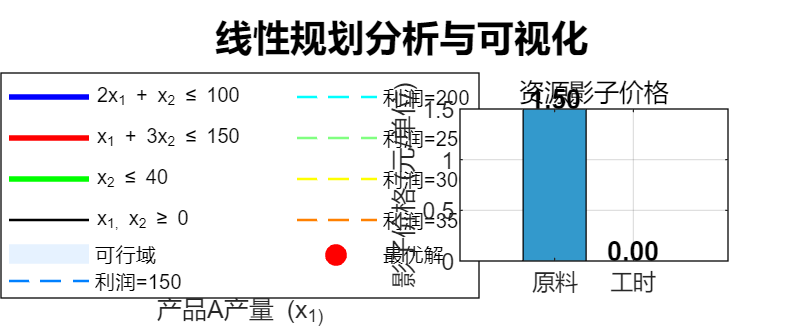


% 可视化影子价格
bar_data = [lambda.ineqlin(1), lambda.ineqlin(2)];
bar(bar_data, 'FaceColor', [0.2, 0.6, 0.8])
set(gca, 'XTickLabel', {'原料', '工时'})
ylabel('影子价格 (元/单位)')
title('资源影子价格')
grid on

% 在柱状图上添加数值
for i = 1:length(bar_data)
    text(i, bar_data(i)+0.1, num2str(bar_data(i), '%.2f'), ...
        'HorizontalAlignment', 'center', 'FontWeight', 'bold')
end

sgtitle('线性规划分析与可视化', 'FontSize', 14, 'FontWeight', 'bold')

## 第三部分：整数规划 (Integer Programming)


% 3.1 整数规划原理介绍
disp(' ')

disp('=== 整数规划 (Integer Programming) ===')

=== 整数规划 (Integer Programming) ===


disp('整数规划特征：')

整数规划特征：


disp('• 部分或全部决策变量必须取整数值')

• 部分或全部决策变量必须取整数值


disp('• 特别类型：0-1规划（二进制变量）')

• 特别类型：0-1规划（二进制变量）


disp('• 应用：选址问题、排班问题、背包问题等')

• 应用：选址问题、排班问题、背包问题等


disp(' ')

disp('MATLAB函数：intlinprog')

MATLAB函数：intlinprog



% 3.2 整数规划示例：背包问题
disp(' ')

disp('--- 整数规划示例：背包问题 ---')

--- 整数规划示例：背包问题 ---


disp('问题：投资组合选择')

问题：投资组合选择


disp('有5个项目可供投资，每个项目的投资金额和预期收益如下：')

有5个项目可供投资，每个项目的投资金额和预期收益如下：


disp('项目 | 投资金额(万元) | 预期收益(万元)')

项目 | 投资金额(万元) | 预期收益(万元)


disp('-----------------------------------')

-----------------------------------


disp('  1  |       3        |       8')

  1  |       3        |       8


disp('  2  |       4        |      10')

  2  |       4        |      10


disp('  3  |       2        |       6')

  3  |       2        |       6


disp('  4  |       5        |      12')

  4  |       5        |      12


disp('  5  |       6        |      15')

  5  |       6        |      15


disp(' ')

disp('总投资预算：10万元')

总投资预算：10万元


disp('约束：最多选择3个项目')

约束：最多选择3个项目


disp('目标：最大化总收益')

目标：最大化总收益



% 定义整数规划参数
n_projects = 5;
c_ip = -[8; 10; 6; 12; 15];  % 目标函数系数（求最大化，所以加负号）

% 约束1：投资总额不超过10万元
A_ip = [3, 4, 2, 5, 6];
b_ip = 10;

% 约束2：最多选择3个项目
A_ip = [A_ip; ones(1, n_projects)];
b_ip = [b_ip; 3];

% 定义整数变量（全部为0-1变量）
intcon = 1:n_projects;  % 所有变量都是整数变量
lb_ip = zeros(n_projects, 1);
ub_ip = ones(n_projects, 1);

% 求解整数规划
options_ip = optimoptions('intlinprog', 'Display', 'iter');
[x_ip, fval_ip, exitflag_ip, output_ip] = ...
    intlinprog(c_ip, intcon, A_ip, b_ip, [], [], lb_ip, ub_ip, [], options_ip);

LP:                Optimal objective value is -26.500000.                                           

Heuristics:        Found 2 solutions using ZI round.                                                
                   Upper bound is -16.000000.                                                       
                   Relative gap is 58.82%.                                                         

Heuristics:        Found 1 solution using ZI round.                                                 
                   Upper bound is -24.000000.                                                       
                   Relative gap is 8.00%.                                                          

Cut Generation:    Applied 1 Gomory cut, and 1 mir cut.                                             
                   Lower bound is -26.000000.                                                       
                   Relative gap is 0.00%.                                                 


% 显示结果
disp(' ')

disp('=== 求解结果 ===')

=== 求解结果 ===


if exitflag_ip == 1 || exitflag_ip == 2
    disp('求解成功！')
    disp('投资方案：')
    total_investment = 0;
    total_return = 0;
    for i = 1:n_projects
        if x_ip(i) > 0.5  % 考虑数值误差
            disp(['  项目', num2str(i), '：投资', num2str(A_ip(i)),'万元，预期收益', num2str(c_ip(i)), '万元'])
            total_investment = total_investment + A_ip(i);
            total_return = total_return + c_ip(i);
        end
    end
    disp(['总投资：', num2str(total_investment), ' 万元'])
    disp(['总收益：', num2str(-total_return), ' 万元'])
    disp(['预算使用率：', num2str(100*total_investment/10, '%.1f'), '%'])
else
    disp('求解失败，退出标志：', num2str(exitflag_ip))
end

求解成功！


投资方案：


  项目1：投资3万元，预期收益-8万元
  项目3：投资4万元，预期收益-6万元
  项目4：投资1万元，预期收益-12万元


总投资：8 万元


总收益：26 万元


预算使用率：80.0%



% 3.3 混合整数规划示例：固定成本问题
disp(' ')

disp('--- 混合整数规划示例：固定成本问题 ---')

--- 混合整数规划示例：固定成本问题 ---


disp('问题：生产设备选择')

问题：生产设备选择


disp('工厂需要生产一种产品，有两种设备可供选择：')

工厂需要生产一种产品，有两种设备可供选择：


disp('设备A：固定成本1000元，单位生产成本8元，最大产量200单位')

设备A：固定成本1000元，单位生产成本8元，最大产量200单位


disp('设备B：固定成本800元，单位生产成本10元，最大产量150单位')

设备B：固定成本800元，单位生产成本10元，最大产量150单位


disp('需求：至少需要生产250单位产品')

需求：至少需要生产250单位产品


disp('目标：最小化总成本')

目标：最小化总成本



% 建模技巧：使用大M法处理固定成本
% 决策变量：x_A, x_B为产量，y_A, y_B为是否使用设备（0-1变量）
M = 10000;  % 大M

% 目标函数：最小化总成本 = 固定成本 + 可变成本
c_mip = [8, 10, 1000, 800];  % [x_A, x_B, y_A, y_B]

% 约束1：总产量 ≥ 250
A_mip = [-1, -1, 0, 0];  % -x_A - x_B ≤ -250
b_mip = -250;

% 约束2：如果使用设备A，则x_A ≤ 200，否则x_A = 0
A_mip = [A_mip; 1, 0, -M, 0];  % x_A - M*y_A ≤ 0
b_mip = [b_mip; 0];

% 约束3：如果使用设备B，则x_B ≤ 150，否则x_B = 0
A_mip = [A_mip; 0, 1, 0, -M];  % x_B - M*y_B ≤ 0
b_mip = [b_mip; 0];

% 整数变量：y_A, y_B是0-1变量
intcon_mip = [3, 4];
lb_mip = [0, 0, 0, 0];
ub_mip = [Inf, Inf, 1, 1];

% 求解混合整数规划
options_mip = optimoptions('intlinprog', 'Display', 'off');
[x_mip, fval_mip, exitflag_mip] = ...
    intlinprog(c_mip, intcon_mip, A_mip, b_mip, [], [], lb_mip, ub_mip, [], options_mip);

% 显示结果
disp(' ')

disp('=== 求解结果 ===')

=== 求解结果 ===


if exitflag_mip == 1 || exitflag_mip == 2
    disp('求解成功！')
    disp(['设备A：', num2str(x_mip(1)), ' 单位，是否使用：', num2str(x_mip(3))])
    disp(['设备B：', num2str(x_mip(2)), ' 单位，是否使用：', num2str(x_mip(4))])
    disp(['总产量：', num2str(x_mip(1)+x_mip(2)), ' 单位'])
    disp(['总成本：', num2str(fval_mip), ' 元'])
    
    % 成本分解
    fixed_cost = x_mip(3)*1000 + x_mip(4)*800;
    variable_cost = 8*x_mip(1) + 10*x_mip(2);
    disp(['  固定成本：', num2str(fixed_cost), ' 元'])
    disp(['  可变成本：', num2str(variable_cost), ' 元'])
else
    disp('求解失败')
end

求解成功！


设备A：250 单位，是否使用：1


设备B：0 单位，是否使用：0


总产量：250 单位


总成本：3000 元


  固定成本：1000 元


  可变成本：2000 元


## 第四部分：非线性规划 (Nonlinear Programming)


% 4.1 非线性规划原理介绍
disp(' ')

disp('=== 非线性规划 (Nonlinear Programming) ===')

=== 非线性规划 (Nonlinear Programming) ===


disp('非线性规划特征：')

非线性规划特征：


disp('• 目标函数或约束条件是非线性的')

• 目标函数或约束条件是非线性的


disp('• 求解方法：梯度下降、牛顿法、内点法等')

• 求解方法：梯度下降、牛顿法、内点法等


disp('• MATLAB函数：fmincon, fminunc')

• MATLAB函数：fmincon, fminunc


disp(' ')


% 4.2 非线性规划示例：最小化成本函数
disp(' ')

disp('--- 非线性规划示例：最小化成本函数 ---')

--- 非线性规划示例：最小化成本函数 ---


disp('问题：确定最优生产批量')

问题：确定最优生产批量


disp('总成本 = 生产准备成本 + 库存持有成本')

总成本 = 生产准备成本 + 库存持有成本


disp('年需求量：D = 10000 单位')

年需求量：D = 10000 单位


disp('每次生产准备成本：S = 100 元')

每次生产准备成本：S = 100 元


disp('单位产品年持有成本：H = 0.5 元')

单位产品年持有成本：H = 0.5 元


disp('生产批量：Q（决策变量）')

生产批量：Q（决策变量）


disp(' ')

disp('总成本函数：TC(Q) = (D/Q)*S + (Q/2)*H')

总成本函数：TC(Q) = (D/Q)*S + (Q/2)*H


disp('约束：Q > 0')

约束：Q > 0



% 使用fmincon求解非线性规划
% 目标函数
D = 10000; S = 100; H = 0.5;
cost_func = @(Q) (D./Q)*S + (Q/2)*H;

% 初始猜测
Q0 = 500;

% 约束：Q > 0（实际上需要Q >= 1，因为不能生产小数个）
A_nlp = [];
b_nlp = [];
Aeq_nlp = [];
beq_nlp = [];
lb_nlp = 1;
ub_nlp = Inf;

% 求解
options_nlp = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp');
[Q_opt, TC_opt, exitflag_nlp, output_nlp] = ...
    fmincon(cost_func, Q0, A_nlp, b_nlp, Aeq_nlp, beq_nlp, lb_nlp, ub_nlp, [], options_nlp);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           2    2.125000e+03     0.000e+00     1.000e+00     0.000e+00     3.750e+00  
    1           4    2.111049e+03     0.000e+00     1.000e+00     3.750e+00     3.691e+00  
    2           6    2.045514e+03     0.000e+00     1.000e+00     1.845e+01     3.417e+00  
    3           8    1.797645e+03     0.000e+00     1.000e+00     8.543e+01     2.458e+00  
    4          10    1.416289e+03     0.000e+00     1.000e+00     2.191e+02     1.213e+00  
    5          12    1.221444e+03     0.000e+00     1.000e+00     2.134e+02     6.743e-01  
    6          14    1.091787e+03     0.000e+00     1.000e+00     2.671e+02     3.352e-01  
    7          16    1.029253e+03     0.000e+00     1.000e+00     2.640e+02     1.551e-01  
    8          18    1.005645e+03     0.000e+00     1.000e+00     2.273e+02     5.


% 显示结果
disp(' ')

disp('=== 求解结果 ===')

=== 求解结果 ===


if exitflag_nlp > 0
    disp('求解成功！')
    disp(['最优生产批量：Q* = ', num2str(Q_opt, '%.1f'), ' 单位'])
    disp(['最小总成本：TC* = ', num2str(TC_opt, '%.2f'), ' 元'])
    
    % 验证经济订货批量公式 EOQ = √(2DS/H)
    EOQ_formula = sqrt(2*D*S/H);
    disp(['EOQ公式计算：Q = √(2DS/H) = ', num2str(EOQ_formula, '%.1f'), ' 单位'])
    disp(['误差：', num2str(abs(Q_opt - EOQ_formula)/EOQ_formula*100, '%.2f'), '%'])
else
    disp('求解失败')
end

求解成功！


最优生产批量：Q* = 2000.0 单位


最小总成本：TC* = 1000.00 元


EOQ公式计算：Q = √(2DS/H) = 2000.0 单位


误差：0.00%


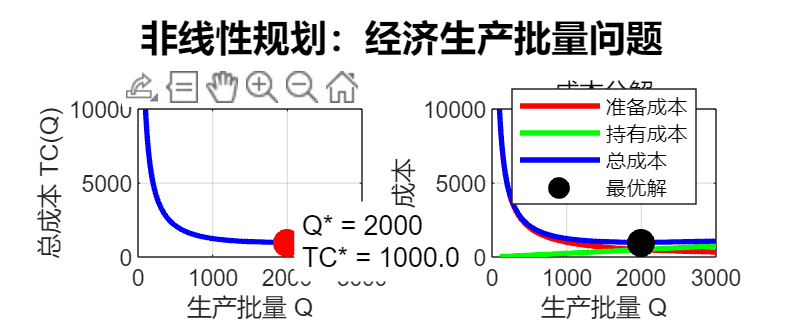


% 4.3 可视化成本函数
figure('Position', [100, 100, 1000, 400])

% 成本函数曲线
subplot(1, 2, 1)
Q_range = 100:10:3000;
TC_range = arrayfun(cost_func, Q_range);

plot(Q_range, TC_range, 'b-', 'LineWidth', 2)
hold on
plot(Q_opt, TC_opt, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r')
xlabel('生产批量 Q')
ylabel('总成本 TC(Q)')
title('经济生产批量模型')
grid on

% 添加最优解标记
text(Q_opt*1.1, TC_opt*1.05, ...
    sprintf('Q* = %.0f\nTC* = %.1f', Q_opt, TC_opt), ...
    'FontSize', 10, 'BackgroundColor', 'white')

% 成本分解
subplot(1, 2, 2)
setup_cost = (D./Q_range)*S;
holding_cost = (Q_range/2)*H;

plot(Q_range, setup_cost, 'r-', 'LineWidth', 2, 'DisplayName', '准备成本')
hold on
plot(Q_range, holding_cost, 'g-', 'LineWidth', 2, 'DisplayName', '持有成本')
plot(Q_range, TC_range, 'b-', 'LineWidth', 2, 'DisplayName', '总成本')
plot(Q_opt, TC_opt, 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'k', 'DisplayName', '最优解')

xlabel('生产批量 Q')
ylabel('成本')
title('成本分解')
legend('Location', 'best')
grid on

sgtitle('非线性规划：经济生产批量问题', 'FontSize', 14, 'FontWeight', 'bold')


% 4.4 带约束的非线性规划示例
disp(' ')

disp('--- 带约束的非线性规划示例 ---')

--- 带约束的非线性规划示例 ---


disp('问题：最小化容器表面积')

问题：最小化容器表面积


disp('设计一个圆柱形容器，体积固定为V = 1000 cm³')

设计一个圆柱形容器，体积固定为V = 1000 cm³


disp('决策变量：半径r，高度h')

决策变量：半径r，高度h


disp('目标：最小化表面积 S = 2πr² + 2πrh')

目标：最小化表面积 S = 2πr² + 2πrh


disp('约束：体积 V = πr²h = 1000')

约束：体积 V = πr²h = 1000


disp('      r ≥ 1, h ≥ 1')

      r ≥ 1, h ≥ 1



% 定义目标函数
surf_area = @(x) 2*pi*x(1)^2 + 2*pi*x(1)*x(2);

% 非线性约束：体积 = 1000
nonlcon = @(x) deal([], pi*x(1)^2*x(2) - 1000);

% 线性约束：无
A = [];
b = [];
Aeq = [];
beq = [];
lb = [1; 1];
ub = [Inf; Inf];

% 初始猜测
x0 = [5; 10];

% 求解
options_nlp2 = optimoptions('fmincon', 'Display', 'iter');
[x_opt2, fval_opt2, exitflag_nlp2] = ...
    fmincon(surf_area, x0, A, b, Aeq, beq, lb, ub, nonlcon, options_nlp2);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.712389e+02    2.146e+02    2.148e-07
    1       6    5.603376e+02    1.651e+01    9.379e+00    6.627e-01
    2      10    5.548131e+02    7.538e-01    5.513e+00    1.678e+00
    3      14    5.535834e+02    3.368e-02    2.747e-01    8.570e-01
    4      18    5.535812e+02    3.737e-06    2.750e-02    1.270e-01
    5      21    5.535808e+02    7.484e-04    4.476e-04    1.115e-02
    6      24    5.535810e+02    8.387e-08    3.431e-05    1.159e-04

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。


% 显示结果
disp(' ')

disp('=== 求解结果 ===')

=== 求解结果 ===


if exitflag_nlp2 > 0
    disp('求解成功！')
    disp(['最优半径：r* = ', num2str(x_opt2(1), '%.2f'), ' cm'])
    disp(['最优高度：h* = ', num2str(x_opt2(2), '%.2f'), ' cm'])
    disp(['最小表面积：S* = ', num2str(fval_opt2, '%.2f'), ' cm²'])
    disp(['实际体积：V = πr²h = ', num2str(pi*x_opt2(1)^2*x_opt2(2), '%.1f'), ' cm³'])
    
    % 验证解析解：对于固定体积，最优比例是 h = 2r
    r_analytic = (1000/(2*pi))^(1/3);
    h_analytic = 2*r_analytic;
    disp(' ')
    disp('解析解（h=2r时表面积最小）：')
    disp(['半径：r = (V/(2π))^(1/3) = ', num2str(r_analytic, '%.2f'), ' cm'])
    disp(['高度：h = 2r = ', num2str(h_analytic, '%.2f'), ' cm'])
else
    disp('求解失败')
end

求解成功！


最优半径：r* = 5.42 cm


最优高度：h* = 10.84 cm


最小表面积：S* = 553.58 cm²


实际体积：V = πr²h = 1000.0 cm³


解析解（h=2r时表面积最小）：


半径：r = (V/(2π))^(1/3) = 5.42 cm


高度：h = 2r = 10.84 cm


## 第五部分：多目标优化


% 5.1 多目标优化原理介绍
disp(' ')

disp('=== 多目标优化 (Multi-objective Optimization) ===')

=== 多目标优化 (Multi-objective Optimization) ===


disp('多目标优化特征：')

多目标优化特征：


disp('• 同时优化多个相互冲突的目标')

• 同时优化多个相互冲突的目标


disp('• 不存在唯一最优解，而是Pareto最优解集')

• 不存在唯一最优解，而是Pareto最优解集


disp('• 求解方法：加权法、约束法、遗传算法等')

• 求解方法：加权法、约束法、遗传算法等


disp('• MATLAB函数：gamultiobj (遗传算法)')

• MATLAB函数：gamultiobj (遗传算法)


disp(' ')


% 5.2 多目标优化示例：投资组合问题
disp(' ')

disp('--- 多目标优化示例：投资组合问题 ---')

--- 多目标优化示例：投资组合问题 ---


disp('问题：投资组合优化')

问题：投资组合优化


disp('目标1：最大化预期收益')

目标1：最大化预期收益


disp('目标2：最小化风险（收益方差）')

目标2：最小化风险（收益方差）


disp('约束：投资比例之和为1，每项投资比例在0-1之间')

约束：投资比例之和为1，每项投资比例在0-1之间



% 模拟数据：5种资产的收益和协方差
rng(42);  % 设置随机种子确保结果可重复
n_assets = 5;

% 生成预期收益率（年化）
expected_returns = 0.05 + 0.1*rand(n_assets, 1);

% 生成协方差矩阵（模拟风险）
temp = randn(n_assets, 10);
cov_matrix = temp * temp' / 10;
cov_matrix = cov_matrix + 0.01*eye(n_assets);  % 确保正定

disp('资产预期收益率：')

资产预期收益率：


for i = 1:n_assets
    disp(['  资产', num2str(i), ': ', num2str(100*expected_returns(i), '%.2f'), '%'])
end

  资产1: 8.75%
  资产2: 14.51%
  资产3: 12.32%
  资产4: 10.99%
  资产5: 6.56%



% 定义多目标函数
multi_obj = @(x) [-x * expected_returns;  % 最大化收益（取负）
                   x * cov_matrix * x'];    % 最小化风险

% 约束：投资比例之和为1
Aeq_mo = ones(1, n_assets);
beq_mo = 1;

% 边界：每项投资在0-1之间
lb_mo = zeros(n_assets, 1);
ub_mo = ones(n_assets, 1);

% 使用遗传算法求解多目标优化
disp(' ')

disp('正在使用遗传算法求解多目标优化...（可能需要几秒钟）')

正在使用遗传算法求解多目标优化...（可能需要几秒钟）


options_mo = optimoptions('gamultiobj', ...
    'PopulationSize', 100, ...
    'ParetoFraction', 0.35, ...
    'MaxGenerations', 200, ...
    'Display', 'final');

[x_mo, fval_mo, exitflag_mo] = gamultiobj(multi_obj, n_assets, ...
    [], [], Aeq_mo, beq_mo, lb_mo, ub_mo, options_mo);

gamultiobj stopped because the average change in the spread of Pareto solutions is less than options.FunctionTolerance.



% 显示结果
disp(' ')

disp('=== 求解结果 ===')

=== 求解结果 ===


找到 35 个Pareto最优解


代表性投资组合：


1. 最小风险组合：


   预期收益：9.53%


   风险（方差）：0.1628


   资产配置：


     资产1: 49.0%
     资产2: 12.5%
     资产3: 9.2%
     资产4: 8.4%
     资产5: 20.8%


2. 最大收益组合：


   预期收益：14.51%


   风险（方差）：0.9886


   资产配置：


     资产2: 100.0%


3. 平衡组合（夏普比率最高）：


   预期收益：10.30%


   风险（方差）：0.1816


   夏普比率：0.242


   资产配置：


     资产1: 40.8%
     资产2: 25.5%
     资产3: 8.0%
     资产4: 8.3%
     资产5: 17.4%


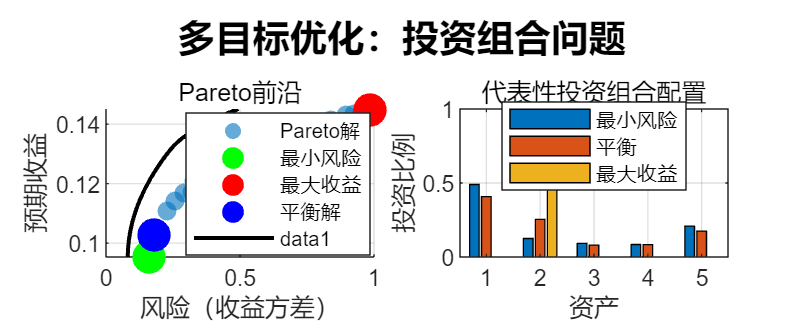

if exitflag_mo >= 0
    disp(['找到 ', num2str(size(x_mo, 1)), ' 个Pareto最优解'])

    % 计算每个解的目标值（注意：第一个目标是负的收益）
    returns = -fval_mo(:, 1);
    risks = fval_mo(:, 2);

    % 找出几个有代表性的解
    [~, min_risk_idx] = min(risks);
    [~, max_return_idx] = max(returns);

    % 寻找平衡解（风险调整后收益最大）
    sharpe_ratio = returns ./ sqrt(risks);
    [~, balanced_idx] = max(sharpe_ratio);

    disp(' ')
    disp('代表性投资组合：')
    disp('1. 最小风险组合：')
    disp(['   预期收益：', num2str(100*returns(min_risk_idx), '%.2f'), '%'])
    disp(['   风险（方差）：', num2str(risks(min_risk_idx), '%.4f')])
    disp('   资产配置：')
    for i = 1:n_assets
        if x_mo(min_risk_idx, i) > 0.01
            disp(['     资产', num2str(i), ': ', num2str(100*x_mo(min_risk_idx, i), '%.1f'), '%'])
        end
    end

    disp(' ')
    disp('2. 最大收益组合：')
    disp(['   预期收益：', num2str(100*returns(max_return_idx), '%.2f'), '%'])
    disp(['   风险（方差）：', num2str(risks(max_return_idx), '%.4f')])
    disp('   资产配置：')
    for i = 1:n_assets
        if x_mo(max_return_idx, i) > 0.01
            disp(['     资产', num2str(i), ': ', num2str(100*x_mo(max_return_idx, i), '%.1f'), '%'])
        end
    end

    disp(' ')
    disp('3. 平衡组合（夏普比率最高）：')
    disp(['   预期收益：', num2str(100*returns(balanced_idx), '%.2f'), '%'])
    disp(['   风险（方差）：', num2str(risks(balanced_idx), '%.4f')])
    disp(['   夏普比率：', num2str(sharpe_ratio(balanced_idx), '%.3f')])
    disp('   资产配置：')
    for i = 1:n_assets
        if x_mo(balanced_idx, i) > 0.01
            disp(['     资产', num2str(i), ': ', num2str(100*x_mo(balanced_idx, i), '%.1f'), '%'])
        end
    end

    % 可视化Pareto前沿
    figure('Position', [100, 100, 1000, 400])

    subplot(1, 2, 1)
    scatter(risks, returns, 50, 'filled', 'MarkerFaceAlpha', 0.6)
    hold on
    plot(risks(min_risk_idx), returns(min_risk_idx), 'go', 'MarkerSize', 12, 'MarkerFaceColor', 'g')
    plot(risks(max_return_idx), returns(max_return_idx), 'ro', 'MarkerSize', 12, 'MarkerFaceColor', 'r')
    plot(risks(balanced_idx), returns(balanced_idx), 'bo', 'MarkerSize', 12, 'MarkerFaceColor', 'b')

    xlabel('风险（收益方差）')
    ylabel('预期收益')
    title('Pareto前沿')
    legend('Pareto解', '最小风险', '最大收益', '平衡解', 'Location', 'best')
    grid on

    % 添加有效边界曲线
    % 计算有效边界（仅用于展示）
    n_points = 50;
    target_returns = linspace(min(returns), max(returns), n_points);
    min_risks = zeros(n_points, 1);

    for i = 1:n_points
        % 对于每个目标收益，最小化风险
        target_return = target_returns(i);
        A_qp = [-expected_returns'; expected_returns'];
        b_qp = [-target_return; target_return];
        x0_qp = ones(n_assets, 1)/n_assets;

        % 使用quadprog求解二次规划
        [~, min_risks(i)] = quadprog(cov_matrix, [], A_qp, b_qp, Aeq_mo, beq_mo, lb_mo, ub_mo, x0_qp, ...
            optimoptions('quadprog', 'Display', 'off'));
    end

    % 绘制有效边界
    plot(min_risks, target_returns, 'k-', 'LineWidth', 1.5)

    subplot(1, 2, 2)
    % 绘制三个代表性组合的资产配置
    representative_portfolios = [x_mo(min_risk_idx, :); 
                                 x_mo(balanced_idx, :);
                                 x_mo(max_return_idx, :)];

    bar(representative_portfolios', 'grouped')
    xlabel('资产')
    ylabel('投资比例')
    title('代表性投资组合配置')
    legend({'最小风险', '平衡', '最大收益'}, 'Location', 'best')
    grid on

    sgtitle('多目标优化：投资组合问题', 'FontSize', 14, 'FontWeight', 'bold')
else
    disp('求解失败')
end


%% 第六部分：综合实战案例
% 6.1 生产计划综合优化问题
disp(' ')

disp('=== 综合实战：生产计划优化问题 ===')

=== 综合实战：生产计划优化问题 ===


disp('问题描述：')

问题描述：


disp('工厂生产三种产品，需要确定最优生产计划，考虑：')

工厂生产三种产品，需要确定最优生产计划，考虑：


disp('1. 利润最大化')

1. 利润最大化


disp('2. 资源约束（机器工时、人工、原料）')

2. 资源约束（机器工时、人工、原料）


disp('3. 市场需求限制')

3. 市场需求限制


disp('4. 最小生产批量要求')

4. 最小生产批量要求


disp(' ')


% 定义问题参数
disp('产品信息：')

产品信息：


product_info = table({'A'; 'B'; 'C'}, ...
                     [30; 40; 35], ...      % 单位利润（元）
                     [5; 7; 6], ...         % 机器工时（小时/单位）
                     [3; 4; 3.5], ...       % 人工（小时/单位）
                     [2; 3; 2.5], ...       % 原料（kg/单位）
                     [0; 0; 50], ...        % 最小生产量
                     [Inf; 200; 150], ...   % 最大生产量（市场需求）
                     'VariableNames', {'Product', 'Profit', 'Machine', 'Labor', 'Material', 'MinQty', 'MaxQty'});
disp(product_info)

    Product    Profit    Machine    Labor    Material    MinQty    MaxQty
    _______    ______    _______    _____    ________    ______    ______

     {'A'}       30         5          3         2          0       Inf  
     {'B'}       40         7          4         3          0       200  
     {'C'}       35         6        3.5       2.5         50       150  




disp('资源约束：')

资源约束：


resource_limits = table({'Machine'; 'Labor'; 'Material'}, ...
                        [1200; 800; 600], ...
                        'VariableNames', {'Resource', 'Available'});
disp(resource_limits)

      Resource      Available
    ____________    _________

    {'Machine' }      1200   
    {'Labor'   }       800   
    {'Material'}       600   




% 6.2 建立线性规划模型
disp(' ')

disp('--- 线性规划模型 ---')

--- 线性规划模型 ---


disp('假设：可以生产任意数量（连续变量）')

假设：可以生产任意数量（连续变量）



% 决策变量：三种产品的产量
c_lp_case = -product_info.Profit;  % 最大化利润

% 资源约束
A_lp_case = [product_info.Machine'; 
             product_info.Labor';
             product_info.Material'];
b_lp_case = resource_limits.Available;

% 市场需求约束（上界）和最小生产量（下界）
lb_lp_case = product_info.MinQty;
ub_lp_case = product_info.MaxQty;

% 求解线性规划
[x_lp_case, fval_lp_case, exitflag_lp_case] = ...
    linprog(c_lp_case, A_lp_case, b_lp_case, [], [], lb_lp_case, ub_lp_case, ...
     optimoptions('linprog', 'Display', 'off'));

% 显示结果
if exitflag_lp_case == 1
    disp('线性规划结果：')
    total_profit = -fval_lp_case;
    disp(['最大利润：', num2str(total_profit), ' 元'])
    for i = 1:3
        disp(['  产品', product_info.Product{i}, '：', num2str(x_lp_case(i)), ' 单位'])
    end
    
    % 资源使用分析
    resource_used = A_lp_case * x_lp_case;
    disp('资源使用情况：')
    for i = 1:3
        utilization = 100 * resource_used(i) / resource_limits.Available(i);
        disp(['  ', resource_limits.Resource{i}, '：', ...
            num2str(resource_used(i)), '/', num2str(resource_limits.Available(i)), ...
            '（使用率 ', num2str(utilization, '%.1f'), '%）'])
    end
else
    disp('线性规划求解失败')
end

线性规划结果：


最大利润：7150 元


  产品A：180 单位
  产品B：0 单位
  产品C：50 单位


资源使用情况：


  Machine：1200/1200（使用率 100.0%）
  Labor：715/800（使用率 89.4%）
  Material：485/600（使用率 80.8%）



% 6.3 建立整数规划模型
disp(' ')

disp('--- 整数规划模型 ---')

--- 整数规划模型 ---


disp('假设：产品必须按整数单位生产')

假设：产品必须按整数单位生产



% 所有变量都是整数
intcon_case = 1:3;

% 求解整数规划
[x_ip_case, fval_ip_case, exitflag_ip_case] = ...
    intlinprog(c_lp_case, intcon_case, A_lp_case, b_lp_case, [], [], ...
    lb_lp_case, ub_lp_case, [], optimoptions('intlinprog', 'Display', 'off'));

% 显示结果
if exitflag_ip_case == 1 || exitflag_ip_case == 2
    disp('整数规划结果：')
    total_profit_ip = -fval_ip_case;
    disp(['最大利润：', num2str(total_profit_ip), ' 元'])
    for i = 1:3
        disp(['  产品', product_info.Product{i}, '：', num2str(x_ip_case(i)), ' 单位'])
    end
    
    % 与线性规划比较
    profit_difference = total_profit_ip - total_profit;
    disp(['与线性规划结果差异：', num2str(profit_difference), ' 元'])
    
    % 资源使用分析
    resource_used_ip = A_lp_case * x_ip_case;
    disp('资源使用情况：')
    for i = 1:3
        utilization = 100 * resource_used_ip(i) / resource_limits.Available(i);
        disp(['  ', resource_limits.Resource{i}, '：', ...
            num2str(resource_used_ip(i)), '/', num2str(resource_limits.Available(i)), ...
            '（使用率 ', num2str(utilization, '%.1f'), '%）'])
    end
else
    disp('整数规划求解失败')
end

整数规划结果：


最大利润：7150 元


  产品A：180 单位
  产品B：0 单位
  产品C：50 单位


与线性规划结果差异：0 元


资源使用情况：


  Machine：1200/1200（使用率 100.0%）
  Labor：715/800（使用率 89.4%）
  Material：485/600（使用率 80.8%）



% 6.4 灵敏度分析
disp(' ')

disp('--- 灵敏度分析 ---')

--- 灵敏度分析 ---



% 计算影子价格
[~, ~, ~, ~, lambda_case] = linprog(c_lp_case, A_lp_case, b_lp_case, [], [], ...
    lb_lp_case, ub_lp_case, optimoptions('linprog', 'Display', 'off'));

if ~isempty(lambda_case)
    disp('影子价格（资源增加1单位可增加的利润）：')
    for i = 1:3
        disp(['  ', resource_limits.Resource{i}, '：', ...
            num2str(lambda_case.ineqlin(i), '%.2f'), ' 元/单位'])
    end
    
    % 利润系数允许变化范围
    disp(' ')
    disp('利润系数允许变化范围（保持当前最优解不变）：')
    disp('（注意：实际计算需要更复杂的分析，这里仅示意）')
    
    % 对于简单情况，可以通过求解对偶问题得到
    % 这里简化处理
    for i = 1:3
        if x_lp_case(i) > lb_lp_case(i) && x_lp_case(i) < ub_lp_case(i)
            % 如果产量在内点，允许变化范围较宽
            disp(['  产品', product_info.Product{i}, '：允许较大范围变化'])
        else
            % 如果产量在边界，允许变化范围较窄
            disp(['  产品', product_info.Product{i}, '：允许变化范围有限'])
        end
    end
end

影子价格（资源增加1单位可增加的利润）：


  Machine：6.00 元/单位
  Labor：0.00 元/单位
  Material：0.00 元/单位


利润系数允许变化范围（保持当前最优解不变）：


（注意：实际计算需要更复杂的分析，这里仅示意）


  产品A：允许较大范围变化


  产品B：允许变化范围有限
  产品C：允许变化范围有限


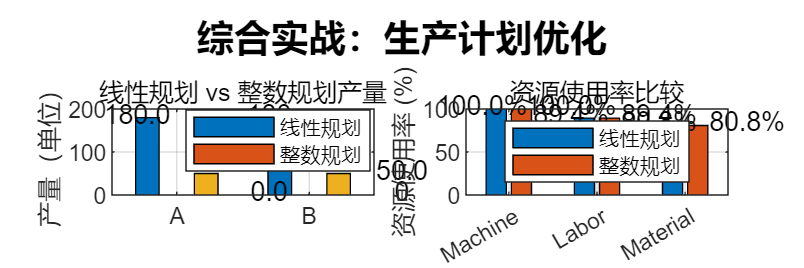


% 6.5 可视化比较
figure('Position', [100, 100, 1200, 400])

% 产量比较
subplot(1, 2, 1)
x_data = [x_lp_case, x_ip_case];
bar(x_data')
set(gca, 'XTickLabel', product_info.Product)
ylabel('产量（单位）')
title('线性规划 vs 整数规划产量')
legend({'线性规划', '整数规划'}, 'Location', 'best')
grid on

% 添加数值标签
for i = 1:3
    text(0.7+(i-1), x_lp_case(i)+max(x_lp_case)/20, num2str(x_lp_case(i), '%.1f'), ...
        'HorizontalAlignment', 'center')
    text(1.7+(i-1), x_ip_case(i)+max(x_ip_case)/20, num2str(x_ip_case(i)), ...
        'HorizontalAlignment', 'center')
end

% 资源使用比较
subplot(1, 2, 2)
resource_util_lp = 100 * resource_used ./ resource_limits.Available;
resource_util_ip = 100 * resource_used_ip ./ resource_limits.Available;

bar([resource_util_lp, resource_util_ip])
set(gca, 'XTickLabel', resource_limits.Resource)
ylabel('资源使用率 (%)')
title('资源使用率比较')
legend({'线性规划', '整数规划'}, 'Location', 'best')
grid on

% 添加数值标签
for i = 1:3
    text(0.7+(i-1), resource_util_lp(i)+5, [num2str(resource_util_lp(i), '%.1f'), '%'], ...
        'HorizontalAlignment', 'center')
    text(1.7+(i-1), resource_util_ip(i)+5, [num2str(resource_util_ip(i), '%.1f'), '%'], ...
        'HorizontalAlignment', 'center')
end

sgtitle('综合实战：生产计划优化', 'FontSize', 14, 'FontWeight', 'bold')

## 第七部分：课程总结与作业


% 7.1 本节课重点总结
disp(' ')
disp('=== 课程总结 ===')
disp('本节课学习了：')
disp('✓ 线性规划：linprog函数，影子价格，灵敏度分析')
disp('✓ 整数规划：intlinprog函数，0-1规划，大M法')
disp('✓ 非线性规划：fmincon函数，约束优化')
disp('✓ 多目标优化：gamultiobj函数，Pareto前沿')
disp('✓ 综合实战：生产计划优化完整案例')
disp(' ')

% 7.2 美赛优化模型选择指南
disp('=== 美赛优化模型选择指南 ===')
disp('根据问题特点选择合适模型：')
disp('1. 线性规划 → 目标函数和约束都是线性的')
disp('2. 整数规划 → 需要离散决策（如是否投资、数量整数）')
disp('3. 非线性规划 → 成本函数非线性、几何优化等')
disp('4. 多目标优化 → 多个相互冲突的目标')
disp('5. 动态规划 → 多阶段决策问题（下节课内容）')
disp(' ')

% 7.3 常见优化问题建模技巧
disp('=== 常见建模技巧 ===')
disp('1. 0-1变量：表示是否选择、开关状态')
disp('2. 大M法：处理固定成本、逻辑约束')
disp('3. 分段线性化：将非线性问题近似为线性')
disp('4. 松弛法：先求解连续问题，再取整')
disp('5. 目标规划：处理多目标时设置优先级')
disp(' ')

% 7.4 课后作业
disp('=== 课后作业 ===')
disp('任务1：运输问题优化')
disp('  某公司有3个工厂，供应4个销售点')
disp('  已知：各工厂产量、各销售点需求、运输成本矩阵')
disp('  要求：建立线性规划模型，求解最小运输成本方案')
disp(' ')

disp('任务2：排班问题')
disp('  医院需要安排护士值班，满足每天不同时段的需求')
disp('  已知：各时段所需护士数、护士连续工作限制')
disp('  要求：建立整数规划模型，求解最少护士数量的排班方案')
disp(' ')

disp('任务3：非线性优化挑战')
disp('  设计一个长方体水箱，容积固定为V')
disp('  已知：底面材料成本为a元/㎡，侧面材料成本为b元/㎡')
disp('  要求：建立非线性规划模型，求解最小成本的设计尺寸')
disp(' ')

% 7.5 下节课预告
disp('=== 下节课预告 ===')
disp('主题：微分方程与动态系统')
disp('内容：')
disp('1. 常微分方程建模与求解')
disp('2. SIR传染病模型')
disp('3. 种群竞争模型')
disp('4. MATLAB微分方程求解器')
disp('5. 动态系统稳定性分析')

% 7.6 清理工作区
disp(' ')
disp('=== 课程结束 ===')
disp('建议保存重要变量：')
disp('  save(''optimization_results.mat'', ''x_lp_case'', ''x_ip_case'')')
disp(' ')
disp('代码已全部执行完毕！请完成课后作业。')

% 可选：保存关键结果
optimization_results = struct();
optimization_results.linear_programming = x_lp_case;
optimization_results.integer_programming = x_ip_case;
optimization_results.profit_lp = -fval_lp_case;
optimization_results.profit_ip = -fval_ip_case;

% 保存到文件
save('optimization_results.mat', 'optimization_results');